# EE3TP3 LAB 3

## ALIASING IN THE TELEPHONE SYSTEM

### PART 1.1

clear
f = 100 %Do a plot of a sampled sinusoid with frequency f = 100 Hz

f = 100

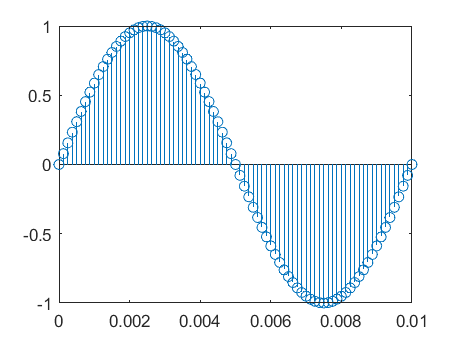

fs = 8000; % Sampling frequency
ts = 1/fs; %interval
tfinalplot = 10e-3; % Set time duration of plot, i.e., 10 msec.
nplot=0:ts:tfinalplot; % Make the time vector for the plot
xnT = sin(2*pi*f*nplot); % Sample the sinusoid.
stem(nplot, xnT); % Make the plot
exportgraphics(gcf, 'lab3_part1a.jpg');

### PART 1.2

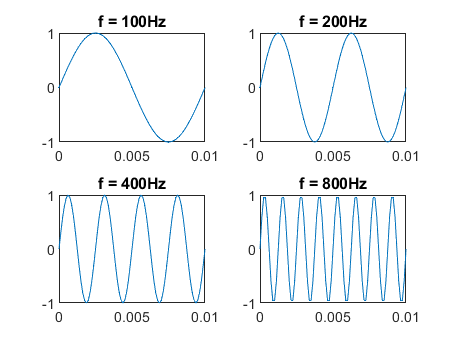

clear
%sinusoid frequencies in Hz
f1 = 100; f2 = 200; f3 = 400; f4 = 800;
fs = 8000; % Sampling frequency in Hz
ts = 1/fs; %interval
tfinalplot = 10e-3; % Set time duration of plot 10 msec.
nplot=0:ts:tfinalplot; % Make the time vector for the plot
tfinal = 2; % Make the time vector for replayed sound spurt
t=0:ts:tfinal; % Play the spurt for 2 seconds

%subplot for sinusoid frequency 100Hz
subplot(2,2,1)
xnT1 = sin(2*pi*f1*t); % Sample the sinusoid
plot(nplot, xnT1(1:length(nplot)));
title('f = 100Hz')

%subplot for sinusoid frequency 200Hz
subplot(2,2,2)
xnT2 = sin(2*pi*f2*t); % Sample the sinusoid
plot(nplot, xnT2(1:length(nplot)));
title('f = 200Hz')

%subplot for sinusoid frequency 400Hz
subplot(2,2,3)
xnT3 = sin(2*pi*f3*t); % Sample the sinusoid
plot(nplot, xnT3(1:length(nplot)));
title('f = 400Hz')

%subplot for sinusoid frequency 800Hz
subplot(2,2,4)
xnT4 = sin(2*pi*f4*t); % Sample the sinusoid
plot(nplot, xnT4(1:length(nplot)));
title('f = 800Hz')

%export data
exportgraphics(gcf, 'lab3_part1b.jpg');

audiowrite('lab3_part1b.wav', cat(2, xnT1, xnT2, xnT3, xnT4), fs);

### PART 1.3

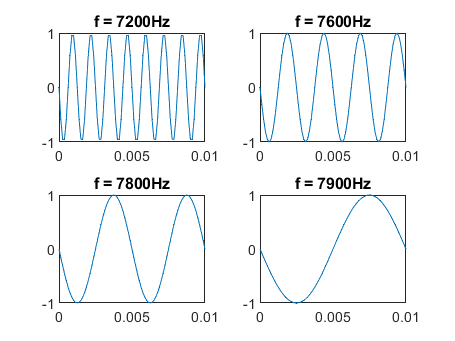

clear
%sinusoid frequencies in Hz
f1 = 7200; f2 = 7600; f3 = 7800; f4 = 7900;
fs = 8000; % Sampling frequency in Hz
ts = 1/fs; %interval
tfinalplot = 10e-3; % Set time duration of plot 10 msec.
nplot=0:ts:tfinalplot; % Make the time vector for the plot
tfinal = 2; % Make the time vector for replayed sound spurt
t=0:ts:tfinal; % Play the spurt for 2 seconds

%subplot for sinusoid frequency 7200Hz
subplot(2,2,1)
xnT1 = sin(2*pi*f1*t); % Sample the sinusoid
plot(nplot, xnT1(1:length(nplot)));
title('f = 7200Hz')

%subplot for sinusoid frequency 7600Hz
subplot(2,2,2)
xnT2 = sin(2*pi*f2*t); % Sample the sinusoid
plot(nplot, xnT2(1:length(nplot)));
title('f = 7600Hz')

%subplot for sinusoid frequency 7800Hz
subplot(2,2,3)
xnT3 = sin(2*pi*f3*t); % Sample the sinusoid
plot(nplot, xnT3(1:length(nplot)));
title('f = 7800Hz')

%subplot for sinusoid frequency 7900Hz
subplot(2,2,4)
xnT4 = sin(2*pi*f4*t); % Sample the sinusoid
plot(nplot, xnT4(1:length(nplot)));
title('f = 7900Hz')

%export data
exportgraphics(gcf, 'lab3_part1c.jpg');

audiowrite('lab3_part1c.wav', cat(2, xnT1, xnT2, xnT3, xnT4), fs);

## ALIASING OF A FREQUENCY CHIRP SIGNAL

### PART 1

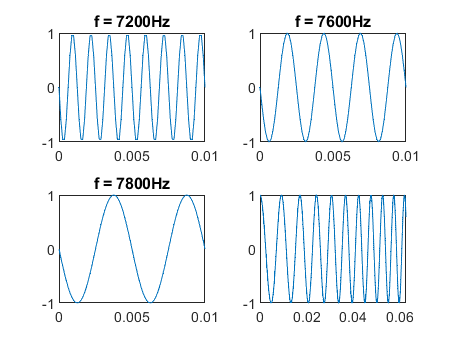

clear
f = 100; %sinusoid frequency in Hz
u = 2000;
fs = 32000; % Sampling frequency in Hz
ts = 1/fs; %interval
nSamples = 2000; %2000 samples
t=0:ts:8; % Make and play the time vector for replayed sound spurt

%plot
cnT = cos(pi*u*t.^2 + 2*pi*f*t); % Sample the sinusoid
plot(t(1:nSamples), cnT(1:nSamples));

%export audio
audiowrite('lab3_part2a.wav', cnT', fs);
exportgraphics(gcf, 'lab3_part2a.jpg');

### PART 2

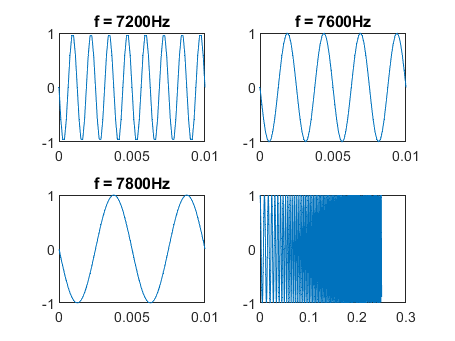

clear
f = 100; %sinusoid frequency in Hz
u = 2000;
fs = 8000; % Sampling frequency in Hz
ts = 1/fs; %interval
nSamples = 2000; %2000 samples
t=0:ts:8; % Make and play the time vector for replayed sound spurt

%plot
cnT = cos(pi*u*t.^2 + 2*pi*f*t); % Sample the sinusoid
plot(t(1:nSamples), cnT(1:nSamples));

%export audio
audiowrite('lab3_part2b.wav', cnT', fs);
exportgraphics(gcf, 'lab3_part2b.jpg');